# Symmetric Matrix-Vector Multiplication (sort of by rows...)

Function MatVec1(A, x, y)  in MatVec1.mlx implements the operation 


$$A x + y $$


computing by rows.   In this Live Script, that function is renamed SymMatVec1 and it is assumed that matrix A is symmetric, with only the lower triangular part stored.  You task is to change the function (at the end of this file) so that it computes the correct result.  You will want to start by copying this into, for example, file MySymMatVec1.mlx, so that you have this current file as a backup.

The below tests this function.  Notice that now the matrix is square (m x m)

m = 4;

Create random $A$, $x$, and $y$.

A = randi( [ -3, 3 ], [ m, m ] )

A =      0     2    -2     0
    -1    -1    -2     3
    -3    -3     0     0
     1    -2     0     3


x = randi( [ -2, 2 ], [ m, 1 ] )

x =      1
     2
    -1
     1


y = randi( [ -2, 2 ], [ m, 1 ] )

y =     -1
     1
     1
    -2


Notice that the matrix is NOT symmetric.  To make it symmetric, we replace the strictly upper triangular part with the transpose of the strictly lower triangular part.  In the command window you can type "help tril" to see how that function works.

Asym = tril( A ) + tril( A,-1 )'

Asym =      0    -1    -3     1
    -1    -1    -3    -2
    -3    -3     0     0
     1    -2     0     3


Compute $A x + y $ with Asym

Asym * x + y

ans =      1
    -1
    -8
    -2


Compare this with the result of the function at the end of this file,  but using the original matrix A.  Before you fix the function, it gives the wrong answer (unless, by accident, the randomly generated problem is special):

SymMatVec1( A, x, y )

ans =      1
    -1
    -8
    -2


if isequal( SymMatVec1( A, x, y ), Asym * x + y )
    disp( 'All is well' );
else
    disp( 'Hmmm, something seems to be wrong' );
end

All is well


The function SymMatVec1( A, x, y ) follows below.  For reference, we give the algorithm for Variant 1:

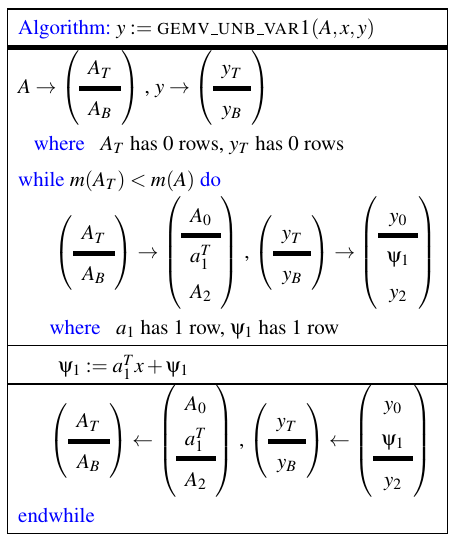

Fix the below function so that only entries on or below the diagonal are used for computation, keeping in mind that A is symmetric.

function [ y_out ] = SymMatVec1( A, x, y )
% Compute y := A x + y 

% Extract the row and column size of A
[ m, n ] = size( A );

% (Strictly speaking you should check that A is square and that x and y are vectors of size  m...)

% Copy y into y_out
y_out = y;

% Compute y_out = A * x + y_out
for i = 1:m
    % For j < i the entries A(i,j) are below the diagonal, and hence stored there
    for j=1:i-1
        y_out( i ) = A( i,j ) * x( j ) + y_out( i );
    end  
    
    % We treat the diagonal entry separate, to emphasize the "splitting of the range" to identify that entry.
    y_out( i ) = A( i,i ) * x( i ) + y_out( i );
    
    % For j > i the entries A(i,j) are above the diagonal, and hence stored in A( j,i )
    for j=i+1:m
        y_out( i ) = A( j,i ) * x( j ) + y_out( i );
    end  
end

end